% load data
clear all
combined_set = readtable("temperature_combined.csv");
x = combined_set{:,1:6}';
y = combined_set{:,7}';

idxTrain = 1:3550;
idxTest = 3551:4176;

x_train = x(:, idxTrain);
y_train = y(:, idxTrain);
x_test = x(:, idxTest);
y_test = y(:, idxTest);
clear combined_set

% define the optimization parameters and ranges
optimVars = [
    optimizableVariable('layerSize', [1 100], 'Type', 'integer');
    optimizableVariable('activationFcn', {'poslin' 'logsig' 'tansig' 'elliotsig'}, 'Type', 'categorical')
]

% define Objective function
fun = @(T)objFcn(T, x, y, idxTrain, idxTest);

% run bayesopt
results = bayesopt(fun,optimVars,...
   'MaxObjectiveEvaluations',2000,...
   'IsObjectiveDeterministic',false,...
   'PlotFcn', [],...
   'UseParallel',true);

## Obtain best hyperparams

bestHyperparameters = bestPoint(results, 'Criterion','min-observed')

bestHyperparameters = 1×2 table
    layerSize    activationFcn
    _________    _____________

       92           logsig    


size = bestHyperparameters.layerSize;
aFcn = bestHyperparameters.activationFcn;

## Train Best Model

rng('default');

% Create a neural network
net = fitnet(size, 'trainbr');
net.layers{1}.transferFcn = string(aFcn);

% Settings for neural network
net.input.processFcns = {'mapstd'};
net.performFcn = 'mse';
net.divideMode = 'sample';
net.trainParam.showWindow = 0;

% Divide data using train and test index
net.divideFcn = 'divideind';
net.divideParam.trainInd  = idxTrain;
net.divideParam.testInd = idxTest;

net.trainParam.showWindow = false;

% Train the network
net = configure(net, x, y);
[temp_shallow_net, temp_shallow_tr] = train(net,x,y);

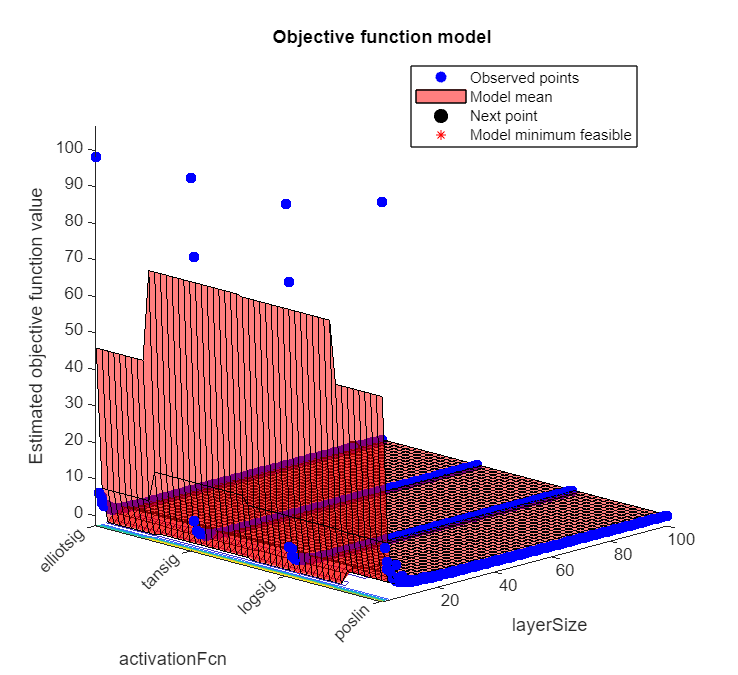

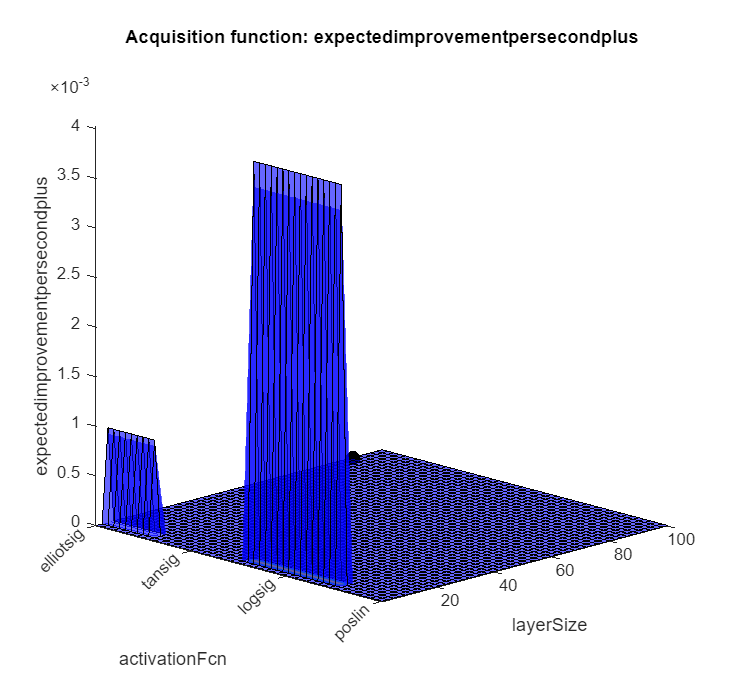

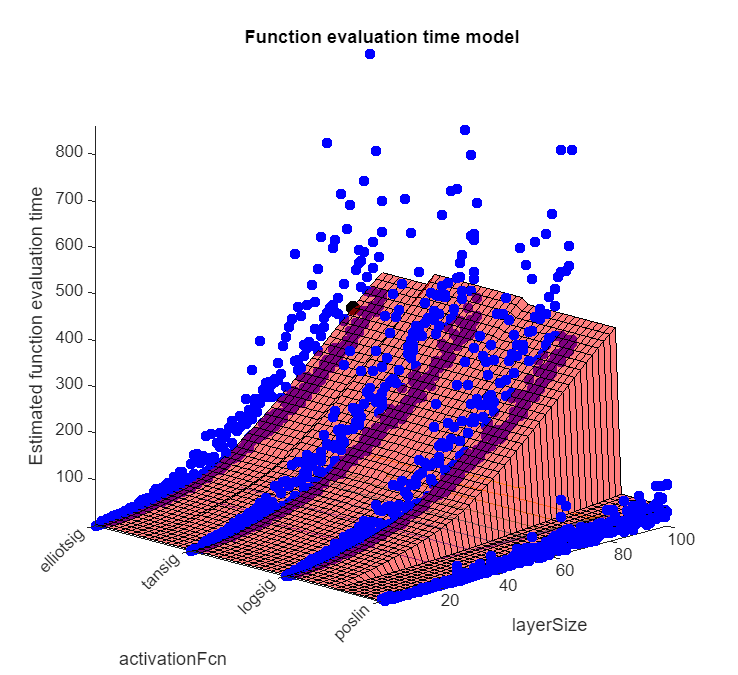

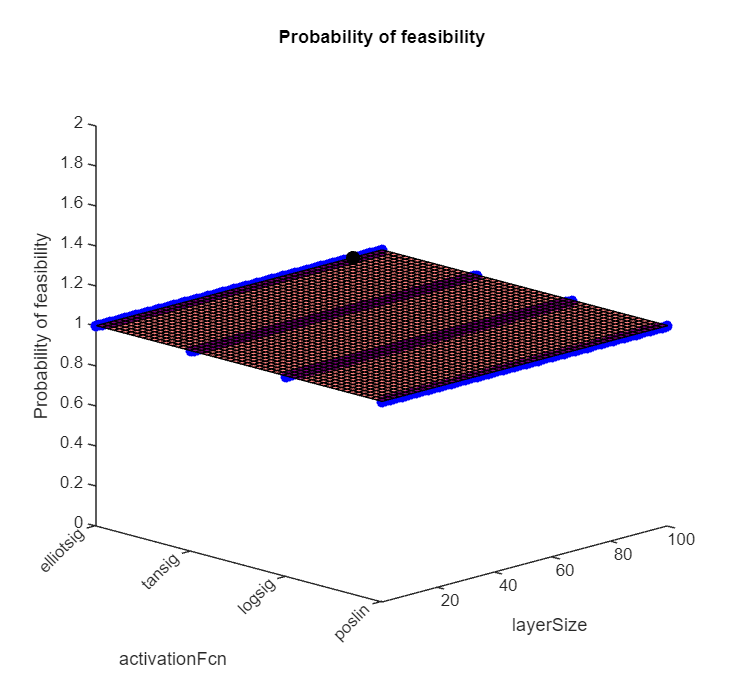

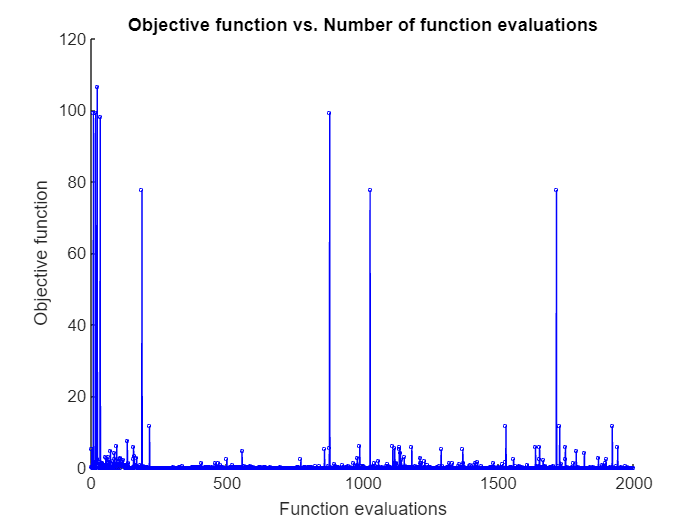

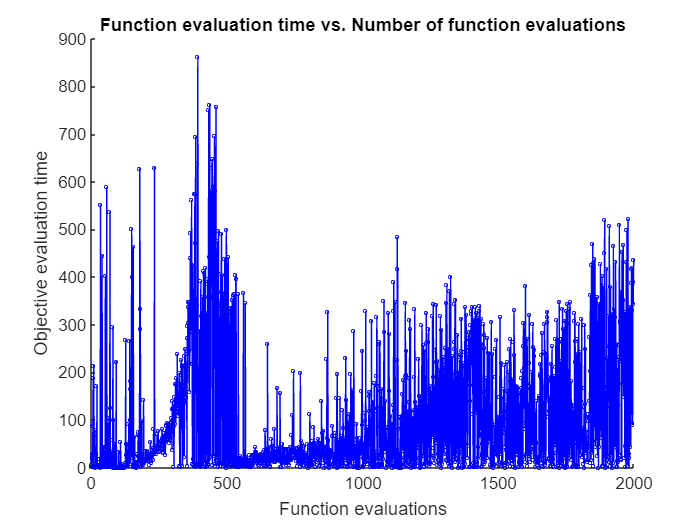

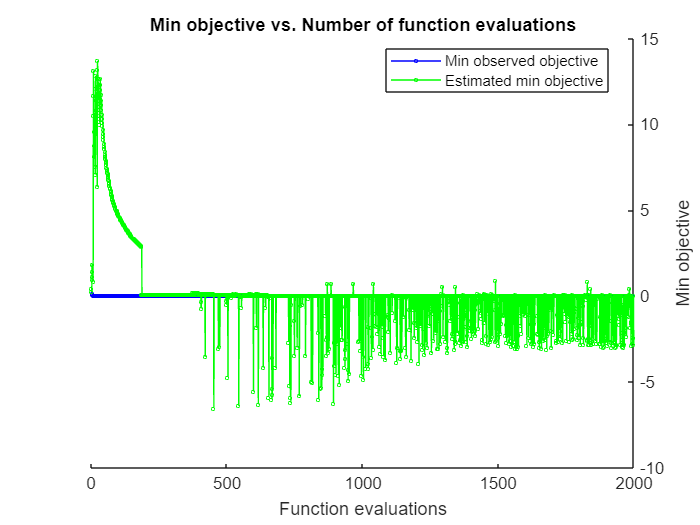

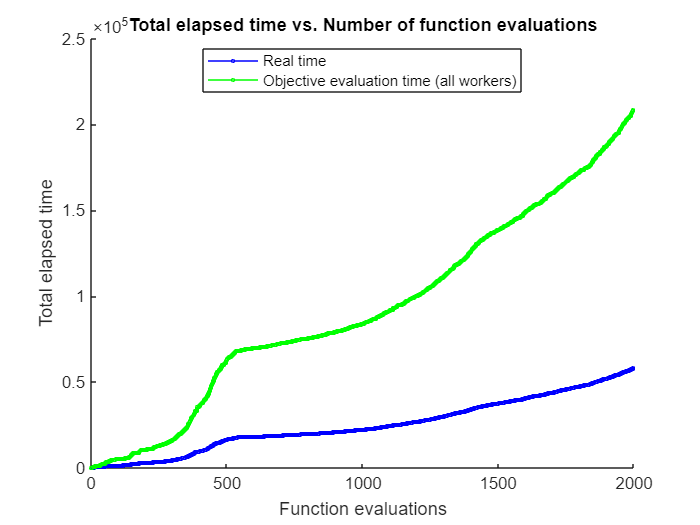

plot(results)

function perf = objFcn(T, x, y, idxTrain, idxTest)
    rng('default');
    % Create a neural network
    net = fitnet(T.layerSize, 'trainbr');
    net.layers{1}.transferFcn = string(T.activationFcn);
    
    % Settings for neural network
    net.input.processFcns = {'mapstd'};
    net.performFcn = 'mse';
    net.divideMode = 'sample';
    net.trainParam.showWindow = 0;
    
    % Divide data using train and test index
    net.divideFcn = 'divideind';
    net.divideParam.trainInd  = idxTrain;
    net.divideParam.testInd = idxTest;

    net.trainParam.showWindow = false;

    % Train the network
    net = configure(net, x, y);
    [~,tr] = train(net,x, y);

    % optimise MSE
    perf = tr.best_tperf;
end